%
%  Emanuele Tocci - @emanueletocci
%
%   Data Science 25-26 course
%   Computer Engineering, Master's Degree
%   Dept. of Information and Electrical Engineering and Applied Mathematics - DIEM
%

% Exercise 2 - MMSE Estimator
% ===================
%
% Model:
%   X_m = Y + W_m
%   W_m ~ N(0, sigma^2)
%   Y   ~ N(0, sigma_prior^2)
%
% Points:
%   a. Calcolare lo stimatore ML
%   b. Calcolare lo stimatore MMSE
%   c. Confrontare i risultati con simulazione Monte Carlo

clear all, close all, clc;

% Datas
N = 100;                % samples
Nmc = 1000;             % monte carlo simulations number
sigma = 1;              % standard deviation of Wn noise
sigma_prior = 0.3;      % standard deviation of Y

for k = 1:Nmc
    Y_true = randn() * sigma_prior;
    Wn = randn(1, N) * sigma;   
    X = Y_true + Wn;

    Y_ML = mean(X);
    Y_MMSE = (sigma_prior^2) / (sigma_prior^2 + sigma^2 / N) * mean(X);

    MSE_ML(k) = (Y_ML - Y_true)^2;
    MSE_MMSE(k) = (Y_MMSE - Y_true)^2;
end

% MMSE estimator minimize the MSE error:



$$\bar \hat Y_{MMSE} = \mathbb E[\bar Y | \bar X] = \int _ \mathbb R yf(y|x)dy = \frac{\sigma^2_{PRIOR}}{\sigma^2_{PRIOR} + \frac{\sigma^2}{N}} * \frac{\sum X_n}{N}$$


% ML estimator maximize the likelihood... ed it is equal to the aritmethic
% mean of X.


$$f(y|x) = \frac{l(x|y)\pi(y)}{m(x)}$$



$$\bar \hat Y _{ML} = g_{ML}(\bar X) =  argmax _g [l(x|y)] = \frac{1}{N}\sum_{m=1}^N\bar X_m$$


% Comparisons
fprintf('True value of Y:      %.4f\n', Y_true);

True value of Y:      -0.0151


fprintf('MLE estimator:        %.4f\n', Y_ML);

MLE estimator:        -0.0063


fprintf('MMSE estimator:       %.4f\n', Y_MMSE);

MMSE estimator:       -0.0057



fprintf('MSE ML:   %.6f\n', mean(MSE_ML));

MSE ML:   0.010546


fprintf('MSE MMSE: %.6f\n', mean(MSE_MMSE));

MSE MMSE: 0.009412


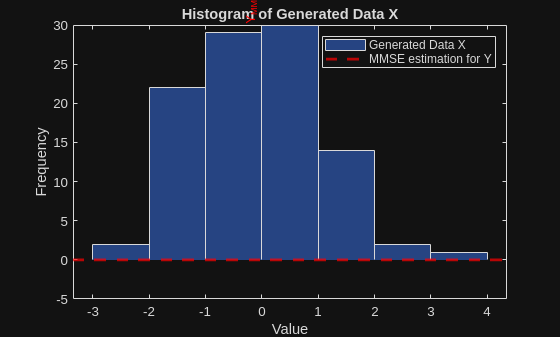


% Plotting

% Supponendo X e Y_MMSE siano già calcolati nell'ultimo esperimento
figure;
histogram(X, 'FaceColor',[0.2 0.4 0.8]); hold on;
yline(Y_MMSE, 'r--', 'LineWidth',2);
legend('Generated Data X','MMSE estimation for Y');
xlabel('Value'); ylabel('Frequency');
title('Histogram of Generated Data X');
text(Y_MMSE, max(histcounts(X)), 'Y_{MMSE}','Color','red','Rotation',90,'VerticalAlignment','bottom');

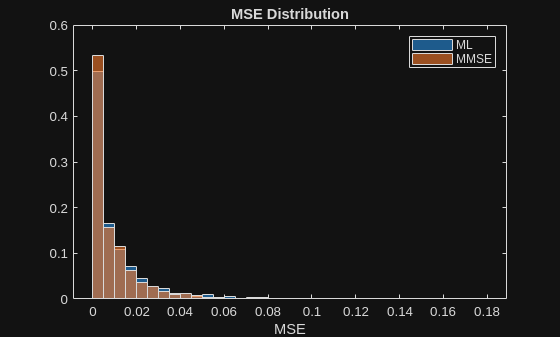



figure;
histogram(MSE_ML, 'Normalization','probability');
hold on;
histogram(MSE_MMSE, 'Normalization','probability');
legend('ML','MMSE');
xlabel('MSE');
title('MSE Distribution');

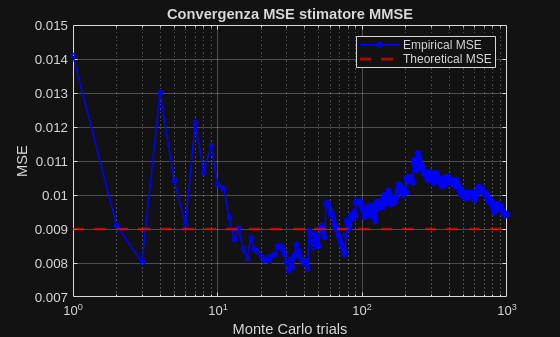


% Calcolo MSE teorico per MMSE (valido per prior e likelihood gaussiani)
S2_theoretical = (sigma^2 * sigma_prior^2) / (N * sigma_prior^2 + sigma^2);

% Prepara il plot della MSE empirica cumulata
MSE_cum = cumsum(MSE_MMSE) ./ (1:Nmc); % Media cumulata

figure;
semilogx(1:Nmc, MSE_cum, 'b-o', 'MarkerSize',3, 'LineWidth',1.2); hold on
yline(S2_theoretical, 'r--', 'LineWidth',2)
legend('Empirical MSE','Theoretical MSE');
xlabel('Monte Carlo trials');
ylabel('MSE');
title('Convergenza MSE stimatore MMSE');
grid on;